# Cinemática para robots móviles

Se conocerán las ecuaciones de cinemática para robots móviles, incluidos los modelos  de monociclo, bicicleta, tracción diferencial y Ackermann.  En este tema se cubren las variables y ecuaciones  de cada modelo de movimiento.

## Cinemática general

El estado del robot se representa como un vector de tres elementos: [x y *θ*].

Para un estado de robot dado:

- x: posición x global del vehículo en metros

- y: posición y global del vehículo en metros

- *θ*: dirección global del vehículo en radianes

Otras variables utiles para la representación en las ecuaciones de cinemática son:

- r: radio de las ruedas en metros

- *ϕ*: velocidad de las ruedas en radianes/segundo

- d: ancho de vía en metros

- l: distancia entre ejes en metros

- *ψ*: ángulo de giro del vehículo en radianes

## Cinemática de uníciclos

Las ecuaciones de cinemática de monociclo modelan una única rueda giratoria que rota en torno a un eje.

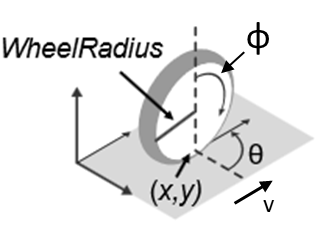

El estado del modelo de monociclo es [x y *θ*].

**Variables**

- x: posición x global del vehículo en metros

- y: posición y global del vehículo en metros

- *θ*: dirección global del vehículo en radianes

- $\dot{\phi}$: velocidad de la rueda en metros/segundo

- r: radio de la rueda en metros

- v: velocidad del vehículo en metros/segundo

- *ω*: velocidad angular de dirección del vehículo en radianes/segundo

Su configuración está descrita por un vector de coordenadas generalizadas: $p=\left\lbrack x\;y\;\theta \right\rbrack$ Es decir, las coordenadas de posición del punto de contacto con el suelo en el sistema de coordenadas fijo $O_{\textrm{xyz}}$, y su ángulo de orientación $\theta$ con respecto al eje x.

La velocidad lineal de la rueda es $v$� y su velocidad angular alrededor de su eje de rotación instantáneo es $\omega \;$. A partir de la figura, obtenemos:

        
$$
    \dot{x} = v \cos \theta \\
    \dot{y} = v \sin \theta \\
    \dot{\theta} = \omega.$$


Eliminando $v$ de las ecuaciones anteriores, se obtiene la restricción de **no deslizamiento lateral**, es decir, el movimiento debe ser **tangencial** a la dirección de orientación $\theta$. Esto implica que la velocidad en la dirección **perpendicular** al chasis debe ser cero:

    
$$\dot{y}cos \theta -\dot{x}sin \theta =0$$


Esta es la **ecuación de restricción no holonómica**, ya que **limita** los movimientos posibles del robot y demuestra que no puede moverse libremente en cualquier dirección instantáneamente.

Tomando en cuenta que $v = r\dot{\phi}}$

        
$$\left[
\begin{array}{cc}
\dot{x} \\
\dot{y} \\
\dot{\theta} \\
\end{array}
\right]
=
\left[
\begin{array}{cc}
r \cos(\theta) & 0 \\
r \sin(\theta) & 0 \\
0 & 1 \\
\end{array}
\right]
\left[
\begin{array}{cc}
\dot{\phi} \\
\omega
\end{array}
\right]
$$


Las ecuaciones del sistema también pueden escribirse en forma matricial: 


$$\dot{\textbf{p}}
=
\left[
\begin{array}{cc}
\dot{x} \\
\dot{y} \\
\dot{\theta} \\
\end{array}
\right]
=
\left[
\begin{array}{cc}
r \cos(\theta) & 0 \\
r \sin(\theta) & 0 \\
0 & 1 \\
\end{array}
\right]
\left[
\begin{array}{cc}
\dot{\phi} \\
\omega
\end{array}
\right]
=
\textbf{J}\textbf{\dot {q}}
$$


Donde **J **es el jacobiano de la $\dot{\;\mathit{\mathbf{q}}}$ es el vector de espacio de juntas o vetor de ecuaciones generalizadas.

En MATLAB se uede crear  el objeto [`unicycleKinematics`](https://la.mathworks.com/help/robotics/ref/unicyclekinematics.html)`, para observar su comportamiento.`

## Cinemática de bicicletas

Las ecuaciones de cinemática de bicicleta modelan un vehículo similar a  un automóvil que acepta el ángulo de giro delantero como una entrada de  control En MATLAB se peude utiliza el objeto [`bicycleKinematics`](docid:robotics_ref#mw_dc3a39e5-3f11-4b64-805e-159698245d2c) 

El modelo de la bicicleta es una simplificación común utilizada en robótica móvil y vehículos autónomos. Describe la cinemática de un vehículo con ruedas sin deslizamiento.

El estado del vehículo está definido por:

- $x$: Posición en el eje X.

- $y$: Posición en el eje Y.

- $\theta$: Orientación del vehículo en el plano respecto al eje X

Las **entradas de control** son:

- v: Velocidad lineal del vehículo.

- ψ: Ángulo de giro de la rueda delantera.

- ω Velocidad angular de la dirección ($\dot{\psi}$).

La **distancia entre ejes** l define la relación entre el ángulo de giro ψ y la velocidad angular del vehículo. Las ecuaciones diferenciales que rigen el movimiento del vehículo �

        
$$\left[
\begin{array}{cc}
\dot{x} \\
\dot{y} \\
\dot{\theta} \\
\end{array}
\right]
=
\left[
\begin{array}{cc}
cos(\theta) & 0\\
sin(\theta) & 0\\
\frac{\tan(\psi)}{l} & 1\\
\end{array}
\right]
\left[
\begin{array}{cc}
v \\
\omega
\end{array}
\right]$$


Donde 

- $\dot{x} = v \cos\theta$ La velocidad en el eje X depende de la orientación θ y la velocidad v.

- $\dot{y} = v \sin\theta$ La velocidad en el eje y también depende de θ y v.

- $\dot\theta =\frac {v}{l} tan \psi $ La orientación cambia de acuerdo con la velocidad y el ángulo de giro ψ. A mayor ψ, mayor curvatura de la trayectoria.

- $\dot{\psi} = \omega$ La variación del ángulo de giro está dada por ω, que indica qué tan rápido se ajusta ψ.

## Cinematica de tracción diferencial

El estado del modelo de tracción diferencial es [x y *θ*].

**Variables**

- x: posición x global del vehículo en metros

- y: posición y global del vehículo en metros

- *θ*: dirección global del vehículo en radianes

- $\dot\phi_L$: velocidad de la rueda izquierda en metros/segundo

- $\dot\phi_R$: velocidad de la rueda derecha en metros/segundo

- r: radio de las ruedas en metros

- d: ancho de vía en metros

- v: velocidad del vehículo en metros/segundo

- *ω*: velocidad angular de dirección del vehículo en radianes/segundo

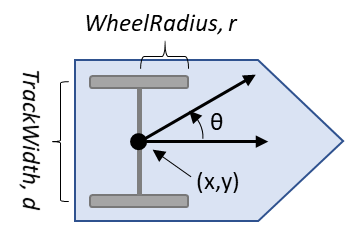

De este modo:


$$\dot{\textbf{p}}
=
\left[
\begin{array}{cc}
\dot{x} \\
\dot{y} \\
\dot{\theta} \\
\end{array}
\right]
=
\left[
\begin{array}{cc}
r \cos(\theta) & r \cos(\theta) \\
r \sin(\theta) & r \sin(\theta) \\
-\frac{r}{d} & \frac{r}{d} \\
\end{array}
\right]
\left[
\begin{array}{cc}
\dot{\phi}_L \\
\dot{\phi}_R
\end{array}
\right]
=
\textbf{J}\textbf{\dot {q}}
$$


## Cinematica tipo Ackermann

Las ecuaciones de cinemática de Ackermann modelan un vehículo similar a  un automóvil con un mecanismo de giro de Ackermann mediante el objeto [`ackermannKinematics`](https://la.mathworks.com/help/robotics/ref/ackermannkinematics.html). La ecuación ajusta la posición de los neumáticos del eje en función del ancho de vía de modo que los neumáticos sigan círculos concéntricos. En términos matemáticos, esto significa que la entrada debe ser la  velocidad angular de dirección de giro $\dot{\psi}$ y no existe un formato generalizado.  

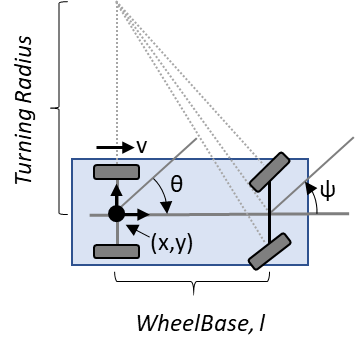

El estado del modelo Ackermann es [x y *θ ψ*].

**Variables**

- x: posición x global del vehículo en metros

- y: posición y global del vehículo en metros

- *θ*: dirección global del vehículo en radianes

- *ψ*: ángulo de giro del vehículo en radianes

- l: distancia entre ejes en metros

- v: velocidad del vehículo en metros/segundo

**Ecuaciones cinemáticas**

En el modelo cinemático de Ackermann, la EDO es:


$$\left[
\begin{array}{cc}
\dot{x} \\
\dot{y} \\
\dot{\theta} \\
\dot{\psi} \\
\end{array}
\right]
=
\left[
\begin{array}{cc}
\cos(\theta) & 0 \\
\sin(\theta) & 0 \\
\tan(\psi)/l & 0 \\
0 & 1 \\
\end{array}
\right]
\left[
\begin{array}{cc}
v \\
\dot{\psi}
\end{array}
\right]
$$


bdclose all    % close all Simulink models
close all      % close all figures
clear          % clear all workspace variables
format compact % compact printout  

## Movimiento de robots con una configuracion de carro o bicicleta

sl_lanechange
out = sim("sl_lanechange")

out =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                      t: [504x1 double] 
                      y: [504x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


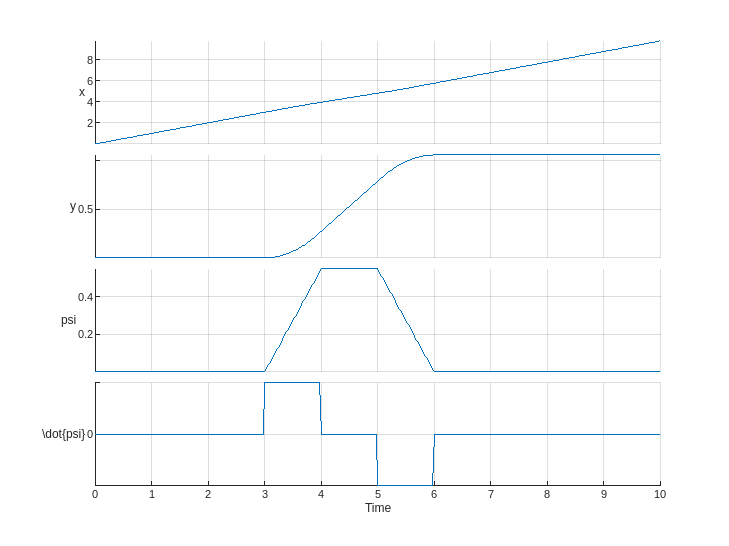

t = out.get("t");
q = out.get("y");
stackedplot(t,q, ...
  DisplayLabels=["x","y","psi","\dot{psi}"], ...
  GridVisible=1,XLabel="Time")

## Conducir sobre una línea

sl_driveline

L = [1 -2 4];
xg = [5 5];
x0 = [8 5 pi/2];
pause(1);
r = sim("sl_driveline");

Failed to load library 'roblocks' referenced by 'sl_driveline/angdiff'.

## Simulación de distintos modelos cinemáticos para robots móviles

Existen varias formas de modelar la cinemática de los robots móviles. Todas ellas determinan la relación que existe entre las velocidades de  rueda y el estado del robot: `[x y theta]`, como coordenadas *xy* y la dirección del robot, `theta`, en radianes.

**Modelo cinemático de monociclo**

La forma más sencilla de representar la cinemática de vehículo de un robot móvil es con un modelo de monociclo, cuya velocidad de rueda está  definida por una rotación sobre un eje central y puede girar en torno a  su eje z. Tanto los modelos cinemáticos con tracción diferencial como  los de bicicleta reducen la cinemática del monociclo cuando las entradas se proporcionan como la velocidad y la tasa de dirección del vehículo, y se ignoran otras restricciones.

unicycle = unicycleKinematics(VehicleInputs="VehicleSpeedHeadingRate");

**Modelo cinemático con tracción diferencial**

El modelo con tracción diferencial utiliza un eje motor posterior para  controlar la velocidad y la tasa de dirección del vehículo. Las ruedas  del eje motor pueden girar en ambas direcciones. Dado que la mayoría de  los robots móviles tienen una interfaz con comandos de rueda de nivel  bajo, este modelo volverá a usar la velocidad y la tasa de dirección del vehículo como entradas para simplificar el control del vehículo.

diffDrive = differentialDriveKinematics(VehicleInputs="VehicleSpeedHeadingRate");

Para diferenciar el comportamiento del modelo de monociclo, puede añadir una restricción de velocidad de la rueda al modelo cinemático con  transmisión diferencial.

diffDrive.WheelSpeedRange = [-10 10]*2*pi;

**Modelo cinemático de bicicleta**

El modelo de bicicleta trata al robot como un modelo similar al de un  automóvil con dos ejes: un eje motor trasero y un eje delantero que gira sobre el eje z. El modelo de bicicleta parte del supuesto de que las  ruedas de cada eje se pueden modelar como una sola rueda centrada y que  la dirección de la rueda delantera se puede ajustar directamente, como  en una bicicleta.

bicycle = bicycleKinematics(VehicleInputs="VehicleSpeedHeadingRate",MaxSteeringAngle=pi/8);

**Modelo cinemático de Ackermann**

El modelo cinemático de Ackermann es un modelo similar al de un automóvil  modificado que asume una dirección de Ackermann. En la mayoría de los  vehículos similares a un automóvil, las ruedas delanteras no giran sobre el mismo eje, sino que giran en ejes ligeramente diferentes para  asegurar que realizan círculos concéntricos alrededor del centro del  giro del vehículo.

carLike = ackermannKinematics;

**Configurar los parámetros de la simulación**

Estos robots móviles seguirán un conjunto de waypoints diseñado para mostrar  algunas diferencias causadas por las distintas cinemáticas.

waypoints = [0 0; 0 10; 10 10; 5 10; 11 9; 4 -5];
% Define the total time and the sample rate
sampleTime = 0.05;               % Sample time [s]
tVec = 0:sampleTime:20;          % Time array
initPose = [waypoints(1,:)'; 0]; % Initial pose (x y theta)

**Crear un controlador del vehículo**

Los vehículos siguen un conjunto de waypoints utilizando un controlador  Pure Pursuit. A partir de un conjunto de waypoints, el estado actual del robot y algunos otros parámetros, el controlador genera la velocidad y  la tasa de dirección del vehículo.

% Define a controller. Each robot requires its own controller
controller1 = controllerPurePursuit(Waypoints=waypoints,DesiredLinearVelocity=3,MaxAngularVelocity=3*pi);
controller2 = controllerPurePursuit(Waypoints=waypoints,DesiredLinearVelocity=3,MaxAngularVelocity=3*pi);
controller3 = controllerPurePursuit(Waypoints=waypoints,DesiredLinearVelocity=3,MaxAngularVelocity=3*pi);

**Simular los modelos con un solver EDO**

Los modelos se simulan utilizando la función `derivative` para actualizar el estado. Este ejemplo utiliza un solver de ecuación  diferencial ordinaria (EDO) para generar una solución. 

Dado que el solver EDO requiere que todas las salidas se proporcionen como  una salida única, el controlador PurePursuit debe estar envuelto en una función que genere la velocidad lineal y la velocidad angular de  dirección como una misma salida. Para dicho efecto se usa un helper de  ejemplo, `exampleHelperMobileRobotController`. El helper de ejemplo asegura también que el robot se detenga cuando se encuentra dentro de un radio especificado del objetivo.

goalPoints = waypoints(end,:)';
goalRadius = 1;

`ode45` se llama una vez por cada tipo de  modelo. La función derivada calcula las salidas de estado, y el estado  inicial viene definido por `initPose`. Cada  derivada acepta el objeto de modelo cinemático correspondiente, la pose  actual del robot y la salida del controlador en dicha pose.

% Compute trajectories for each kinematic model under motion control
[tUnicycle,unicyclePose] = ode45(@(t,y)derivative(unicycle,y,exampleHelperMobileRobotController(controller1,y,goalPoints,goalRadius)),tVec,initPose);
[tBicycle,bicyclePose] = ode45(@(t,y)derivative(bicycle,y,exampleHelperMobileRobotController(controller2,y,goalPoints,goalRadius)),tVec,initPose);
[tDiffDrive,diffDrivePose] = ode45(@(t,y)derivative(diffDrive,y,exampleHelperMobileRobotController(controller3,y,goalPoints,goalRadius)),tVec,initPose);

**Representar los resultados**

Los resultados del solver EDO se pueden visualizar fácilmente en una sola gráfica utilizando `plotTransforms` para visualizar los resultados de todas las trayectorias a la vez. Las salidas de pose se deben convertir primero a matrices indexadas de traslaciones y cuaterniones.

unicycleTranslations = [unicyclePose(:,1:2) zeros(length(unicyclePose),1)];
unicycleRot = axang2quat([repmat([0 0 1],length(unicyclePose),1) unicyclePose(:,3)]);

bicycleTranslations = [bicyclePose(:,1:2) zeros(length(bicyclePose),1)];
bicycleRot = axang2quat([repmat([0 0 1],length(bicyclePose),1) bicyclePose(:,3)]);

diffDriveTranslations = [diffDrivePose(:,1:2) zeros(length(diffDrivePose),1)];
diffDriveRot = axang2quat([repmat([0 0 1],length(diffDrivePose),1) diffDrivePose(:,3)]);

Luego, se puede representar y visualizar en la parte superior el  conjunto de todas las transformadas. Las rutas de los robots de  monociclo, bicicleta y tracción diferencial se muestran en color rojo,  azul y verde, respectivamente. Para simplificar la gráfica, muestre solo una de cada diez salidas.

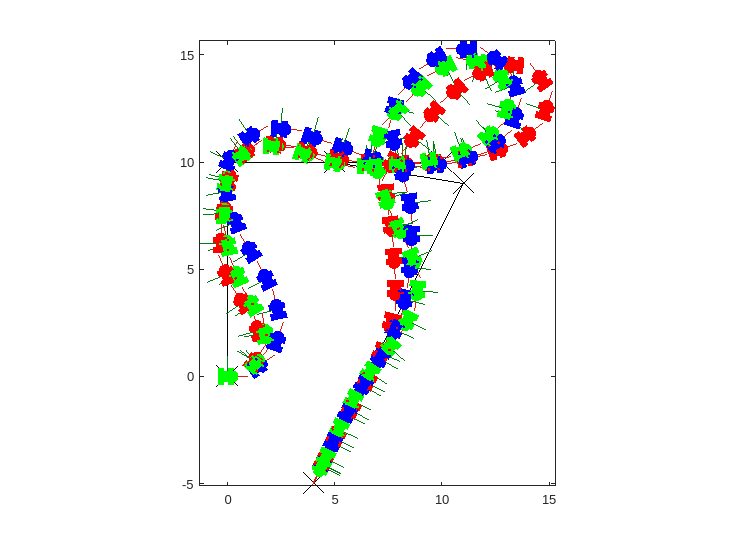

figure
plot(waypoints(:,1),waypoints(:,2),"kx-",MarkerSize=20);
hold all
plotTransforms(unicycleTranslations(1:10:end,:),unicycleRot(1:10:end,:),MeshFilePath="groundvehicle.stl",MeshColor="r");
plotTransforms(bicycleTranslations(1:10:end,:),bicycleRot(1:10:end,:),MeshFilePath="groundvehicle.stl",MeshColor="b");
plotTransforms(diffDriveTranslations(1:10:end,:),diffDriveRot(1:10:end,:),MeshFilePath="groundvehicle.stl",MeshColor="g");
axis equal
view(0,90)

## Referencias

*Peter Corke**; Robotics, Vision and Control. Fundamental Algorithms in MATLAB*; Springer, 2023.

*Spyros G. **Tzafestas**; Introduction to Mobile Robot Control; *Elsevier; 2014

Roland Siegwart; *Introduction to Autonomous Mobile Robots; *MIT Press, 2004 